Ch5 数字滤波器设计

巴特沃斯模拟滤波器零极点 

课本P178 图5-24

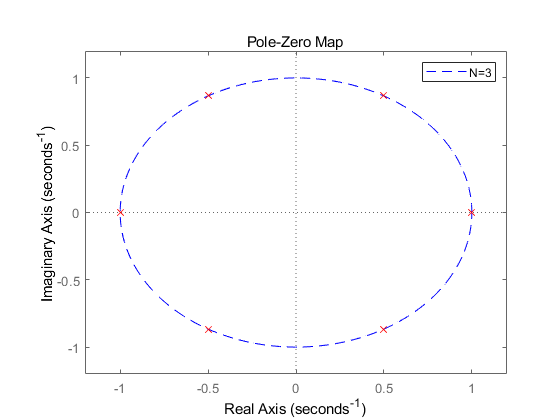

% 巴特沃斯模拟滤波器幅度平方函数极点图
% Butterworth squared magnitude response function

figure;
alpha = 0:0.01:2*pi;
x = cos(alpha);
y = sin(alpha);
plot(x,y,'--b');
hold on;
sys = tf([1],[-1 0 0 0 0 0 1]);
% sys = 
%     -1
%  -------
%  s^6 - 1
h = pzplot(sys,'r');
xlim([-1.2 1.2]);
ylim([-1.2 1.2]);
legend("N=3");

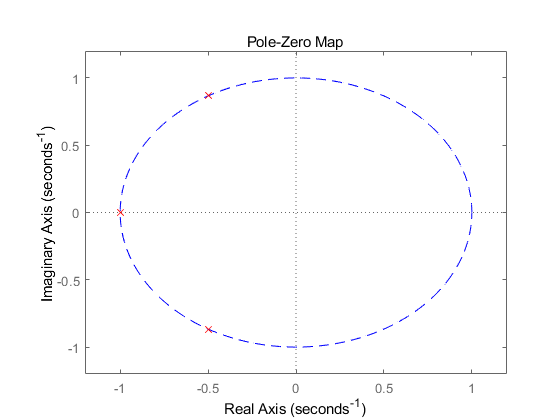



clear; 
close all;
clc;

%--------------------------------------------------------------------------
%极零图
%--------------------------------------------------------------------------
figure;
alpha = 0:0.01:2*pi;
x = cos(alpha);
y = sin(alpha);
plot(x,y,'--b');
hold on;

n = 3;
[z, p, k]=buttap(n);
[num,den] = zp2tf(z,p,k);
hs = tf(num,den);
% hs =
% 
%            1
%  ---------------------
%  s^3 + 2 s^2 + 2 s + 1
pzplot(hs,'r');
xlim([-1.2 1.2]);
ylim([-1.2 1.2]);

xlabel('Real Axis');
ylabel('Imaginary Axis');


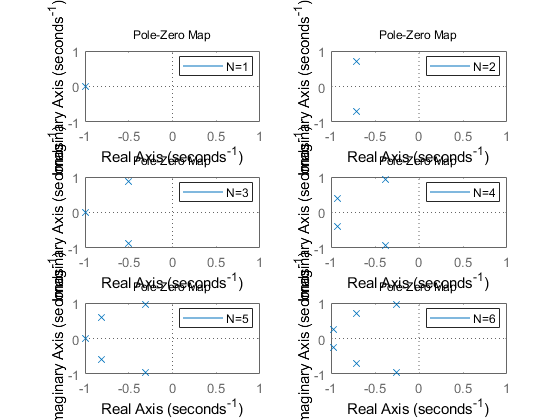


%--------------------------------------------------------------------------
%极零图
%--------------------------------------------------------------------------
figure;
str = ["N=1","N=2","N=3","N=4","N=5","N=6"];
N = 6;
for n = 1:N
    [z, p, k]=buttap(n);
    [num,den] = zp2tf(z,p,k);
    
    subplot(3,2,n);
    hs = tf(num,den);
    zpk(hs);
    pzmap(hs);
    xlim([-1 1]);
    ylim([-1 1]);
    legend(str(n));
    %hold on;    
end